# **SIMPLIFIED MODEL**

## ***1) System analysis***

clear; close all; clc;
 set(0, 'defaultlegendinterpreter', 'latex')
 g = 9.81;
 

Yv_nom = -0.1068;  % [1/s]         -> 4.26 %
Yp_nom = 0.1192;        % [m/(s rad)]   -> 2.03 %
Lv_nom = -5.9755;       % [rad s/m]     -> 1.83 %
Lp_nom = -2.6478;       % [1/s]         -> 2.01 %
Yv = Yv_nom;
Yp = Yp_nom;
Lv = Lv_nom;
Lp = Lp_nom;

Yd_nom = -10.1647;      % [m/s^2]       -> 1.37 %
Ld_nom = 450.7085;      % [rad/s^2]     -> 0.81 %
Yd = Yd_nom;
Ld = Ld_nom;

A_s = [Yv 0 g; 0 Lp 0; 0 1 0];
B_s = [0 Ld 0]';
C_s = [0, 0, 1];
D_s = 0;

sys_s = ss(A_s, B_s, C_s, D_s)

sys_s =
 
  A = 
            x1       x2       x3
   x1  -0.1068        0     9.81
   x2        0   -2.648        0
   x3        0        1        0
 
  B = 
          u1
   x1      0
   x2  450.7
   x3      0
 
  C = 
       x1  x2  x3
   y1   0   0   1
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.


StateName_s = {'v', 'p', '\phi'};
sys_s.u = '\delta';
sys_s.y = '\phi';

G_delta_phi_nom = tf(sys_s)

G_delta_phi_nom =
 
  From input "\delta" to output "\phi":
      450.7
  -------------
  s^2 + 2.648 s
 
Continuous-time transfer function.
Model Properties


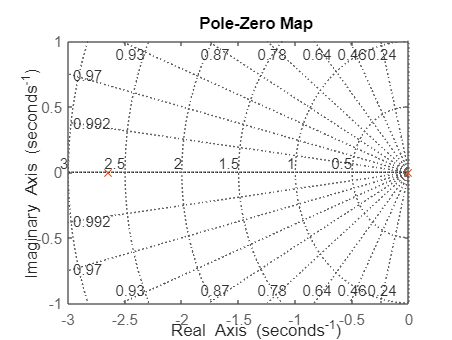

% Pole - Zero Map
figure(1)
pzplot(sys_s);
hold on; grid on 
pzplot(sys_s);

% Zeros
z_delta_phi_tot = tzero(G_delta_phi_nom)


z_delta_phi_tot =

  0×1 empty double column vector



% Poles
p_delta_phi_tot = pole(G_delta_phi_nom)

p_delta_phi_tot =          0
   -2.6478


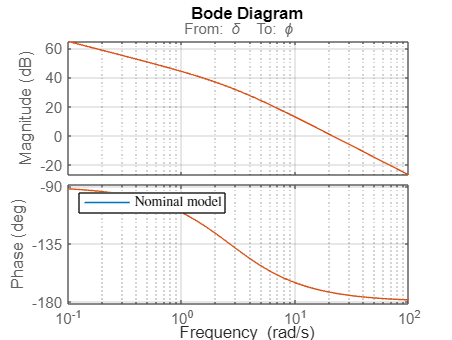

figure
bode(sys_s)
hold on, grid on
bode(sys_s)
legend('Nominal model','Location','northwest')

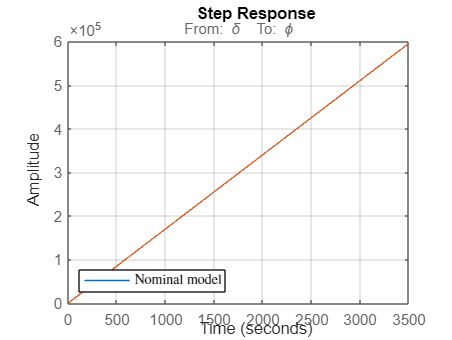

figure 
step(sys_s)
hold on,grid on
step(sys_s)
legend('Nominal model','Location','southwest')

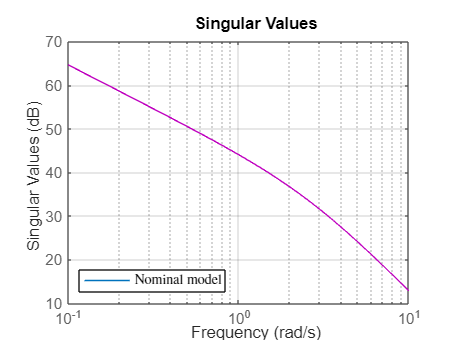

figure
sigma(sys_s)
hold on, grid on
sigma(sys_s, '-m')
legend('Nominal model','Location','southwest')

## **2) Design of DI loop **

Design a DI loop using the simplified model and nominal values for the parameters

***Simplified model***

CAB_inv_s = ss(0, 0, 0, inv(C_s*A_s*B_s));
CAB_inv_s.u = 'e_w' ;
CAB_inv_s.y = '\delta';

C_obs = eye(3,3)

C_obs =      1     0     0
     0     1     0
     0     0     1


sys_state = ss(A_s, B_s ,C_obs , 0);
sys_state.u = '\delta';
sys_state.y = {'v', 'p', '\phi'};

CA_s = ss(zeros(3,3), zeros(3,3), zeros(1,3), C_s*A_s*A_s);
CA_s.u = {'v', 'p', '\phi'};
CA_s.y = 'w_DI';

SumOuter_DI = sumblk('e_w = w - w_DI');

CL_DI = connect(SumOuter_DI, CAB_inv_s, sys_state, CA_s, 'w', {'\phi','\delta'})

CL_DI =
 
  A = 
       x1  x2
   x1   0   0
   x2   1   0
 
  B = 
       w
   x1  1
   x2  0
 
  C = 
                 x1        x2
   \phi           0         1
   \delta  0.005875         0
 
  D = 
                  w
   \phi           0
   \delta  0.002219
 
Continuous-time state-space model.



CL_DI_SISO = connect(SumOuter_DI, CAB_inv_s, sys_state, CA_s, 'w', '\phi')

CL_DI_SISO =
 
  A = 
       x1  x2
   x1   0   0
   x2   1   0
 
  B = 
       w
   x1  1
   x2  0
 
  C = 
         x1  x2
   \phi   0   1
 
  D = 
         w
   \phi  0
 
Continuous-time state-space model.
Model Properties


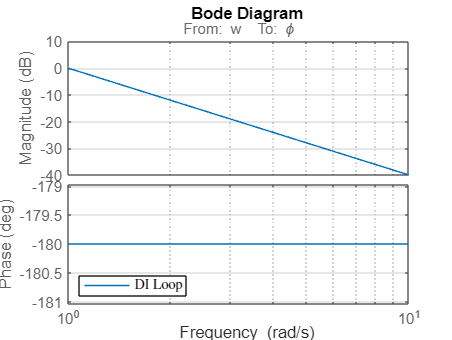


figure
bode(CL_DI_SISO)
legend('DI Loop', 'Location','SouthWest')
grid on

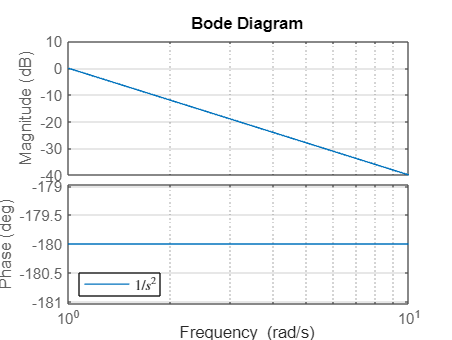


figure
bode(tf(1, [1 0 0]))
legend('$1/s^2$', 'Location','SouthWest')
grid on

**3) DESIGN OF **$R(S)$

The design requirements are:

- Nominal performance: response of $\phi$ to variations in $\phi_0$ equivalent to a second order response with $\omega_n \ge 10 $ rad/s and $\xi \ge 0.9$.

- Control effort limitation: $|\delta_{lat}| < 0.05$ for a given doublet change in $\phi_0$ of 10° amplitude.

- Robust stability: ensure robustness of stability to model uncertainty associated with $\pm 3 \sigma$ ranges on all parameters, treated as deterministic bounds.

Now we proceed to construct our weights on the sensitivities considering each design requirement.

#### a) Nominal performance

Since the response of $\phi$ to variations in $\phi_0$ must be equivalent to a second order response with $\omega_n \ge 10 $ rad/s and $\xi \ge 0.9$. We can compute the settling time and the percentage overshoot of our desired approximated complementary sensitivity transfer function $F_2(s)$.


$$F_2(s)  = \frac{\omega_n^2}{s^2 + 2\xi\omega_ns + \omega_n^2}$$


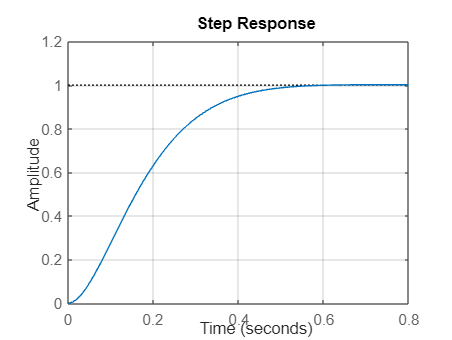

omega_n = 10;       % [rad/s]
xi = 0.9;

s = tf('s');

F_2 = omega_n^2/(s^2 + 2*s*xi*omega_n + omega_n^2);
S_2 = 1-F_2;

figure
step(F_2)
grid on


stepinfo(F_2)

ans = struct with fields:
         RiseTime: 0.2883
    TransientTime: 0.4700
     SettlingTime: 0.4700
      SettlingMin: 0.9024
      SettlingMax: 1.0015
        Overshoot: 0.1524
       Undershoot: 0
             Peak: 1.0015
         PeakTime: 0.7215


$t_{st} \simeq \frac{4}{\xi \omega_n} = 0.47  $ s and $O_{\%} = 100 \, e^{\frac{-\pi\xi}{\sqrt{1 - \xi^2}}} = 0.15 \%$

So we can plot the bode diagram of the magnitude of our desired sensitivity and complementary sensitivity functions. 

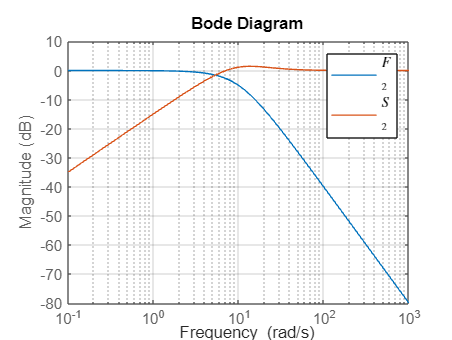

figure
bodemag(F_2)
hold on
bodemag(S_2)
grid on
legend('$F\_2$','$S\_2$','interpreter','latex')

Now we have to design our performance weight $W_p(s)$ that will be used in the $H_\infty$ synthesis. 


$$W_p(s) = \frac{\frac{s}{M} + \omega_b}{s + A \omega_b}$$


The objective is that $1/W_p(s)$ is used to shape our sensitivity function in order to have $S(s) \simeq S_2(s)$.

Where $M$ is related to the peak, $A$ is related to the value at steady state and $\omega_b$ is related to the cross-over frequency and so to the settling time of our response.

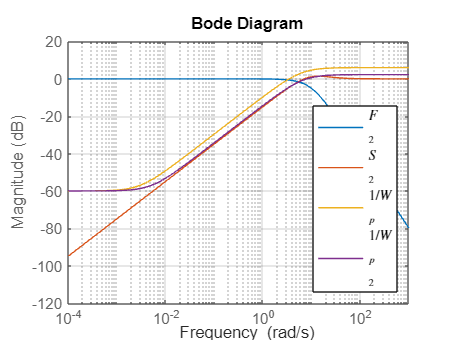

M = 2;
A = 1e-3;
omega_b = 0.3*omega_n;

W_p = (s/M + omega_b)/(s + A*omega_b);
W_p2inv = makeweight(1e-3,8,1.3,0,1);
W_p2 = 1/W_p2inv;

figure
bodemag(F_2)
hold on
bodemag(S_2)
grid on
bodemag(1/W_p)
bodemag(1/W_p2)
legend('$F\_2$','$S\_2$','$1/W\_p$','$1/W\_{p\_{2}}$','interpreter','latex', 'location','southeast')

#### b) Control effort limitation

For the doublet change in $\phi_0$ of 10° amplitude shown in the figure, we want $|\delta_{lat}| < 0.05$

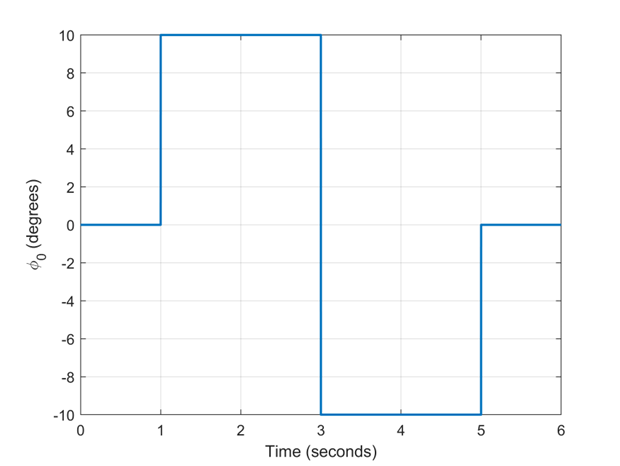

The weight on control sensitivity has the important function to keep the control action moderated; indeed, in practice control action is provided by actuators, which have limited control authority both in range and rate; also, the actuator bandwidth is limited, *i.e.*, one should not demand the actuator a control action which is beyond its capabilities.

We have to design our performance weight $W_q(s)$ that will be used in the $H_\infty$ synthesis.


$$W_q(s) = \alpha \frac{s + \omega_{act} 10^{-3}}{s +  \omega_{act}}$$


where $\omega_{act}$ is related to the frequency of the actuators, while $\alpha$ represent the high frequency gain of the weight $W_q(s)$ and shall be large enough so as to limit the magnitude of $Q(s)$ beyond the bandwidth. In fact for a doublet input in $\phi_0$, we have a large control effort at the beginning of the transient of the input given at 3 s, whose peak can be computed with the initial value theorem using a step input of two times the doublet amplitude


$$\lim_{t\rightarrow0} \delta_{lat} = \lim_{s\rightarrow \infty} s Q(s) \frac{A}{s} = \lim_{s\rightarrow \infty} Q(s) A = \frac{A}{\alpha}$$


since we want to have $|\delta_{lat}| < 0.05$ for $A=$deg2rad$(20)$. 

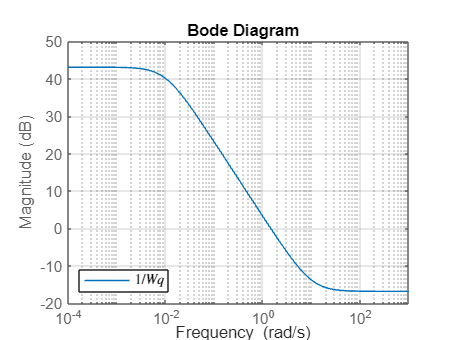

alpha = deg2rad(20)/0.05;
w_tau = 10;

W_q = alpha*(s+w_tau*1e-3)/(s+w_tau);

figure
bodemag(1/W_q)
grid on
legend('$1/Wq$', 'Location','Southwest')

**c) Controller structure**

R_phi = tunablePID2('R_phi', 'PID');
R_phi.c.Value = 0;
R_phi.c.Free = false;
R_phi.b.Value = 1;
R_phi.b.Free = false;
R_phi.Tf.Value = 0.02;
R_phi.Tf.Free = false;
R_phi.u = {'\phi_0','\phi'};
R_phi.y = 'w';


#### Robust stability

We need to ensure stability to model uncertainty associated with $\pm 3 \sigma$ ranges on all parameters, treated as deterministic bounds.

For RS we have to verify that 


$$\left|W(j\omega) \bar{F}(j\omega)\right| < 1 \quad \quad \forall \omega$$


where $\bar{F}(j\omega)$ is the closed-loop nominal complementary sensitivity, while $W(j\omega)$ is a weight related to the uncertainty that represents an upperbound for the relative error between the nominal and the uncertaint plants.

Now we begin without adding this requirement, for the first iteration we use only nominal performance and control effort limitation requirements, and we verify if our result respects RS condition.

** Design using structured Hinf synthesis**

Now we can use [`hinfstruct`](https://it.mathworks.com/help/robust/ref/lti.hinfstruct.html) to tune our controllers. Through this function we can tune the free parameters of the closed loop model to minimize its $H_\infty$ norm.

SumIn = sumblk('e_\phi = \phi_0 - \phi');


W_p.u = 'e_\phi';
W_p.y = 'z_1';

W_q.u = '\delta';
W_q.y = 'z_2';

CL_0 = connect(R_phi, CL_DI, W_p, W_q, SumIn, {'\phi_0'},{'z_1','z_2'}, {'\delta','\phi', 'e_\phi'});


Then we have to define our new closed-loop to be used in the synthesis.1', 'z_2', '\delta'})

Finally we can define options and run `hinfstruct`.

opt = hinfstructOptions('Display','final','RandomStart',10);

[CL,gamma,info] = hinfstruct(CL_0,opt);

Final: Peak gain = 0.821, Iterations = 49
       Some closed-loop poles are marginally stable (decay rate near 1e-07)
Final: Peak gain = 0.821, Iterations = 50
       Some closed-loop poles are marginally stable (decay rate near 1e-07)
Final: Peak gain = 0.821, Iterations = 40
       Some closed-loop poles are marginally stable (decay rate near 1e-07)
Final: Peak gain = 0.821, Iterations = 38
       Some closed-loop poles are marginally stable (decay rate near 1e-07)
Final: Peak gain = 0.821, Iterations = 43
       Some closed-loop poles are marginally stable (decay rate near 1e-07)
Final: Peak gain = 0.821, Iterations = 38
       Some closed-loop poles are marginally stable (decay rate near 1e-07)
Final: Peak gain = 0.821, Iterations = 35
       Some closed-loop poles are marginally stable (decay rate near 1e-07)
Final: Peak gain = 0.821, Iterations = 44
       Some closed-loop poles are marginally stable (decay rate near 1e-07)
Final: Peak gain = 0.821, Iterations = 45
       Some cl

We can proceed analysing our results.

First we can see the value of our controllers free parameters.

showTunable(CL)

R_phi =
 
                       1                s    
  u = Kp (b*r-y) + Ki --- (r-y) + Kd -------- (c*r-y)
                       s              Tf*s+1 

  with Kp = 35.8, Ki = 3.58e-06, Kd = 9.52, Tf = 0.02, b = 1, c = 0
 
Name: R_phi
Continuous-time 2-DOF PIDF controller in parallel form.


R_phi_tuned = CL.blocks.R_phi;
R_phi_tuned.Kp.Free = false;
R_phi_tuned.Kd.Free = false;
R_phi_tuned.Ki.Free = false;
R_phi_tuned.u = {'\phi_0','\phi'};
R_phi_tuned.y = 'w';


The complementary sensitivity can be retrieve.

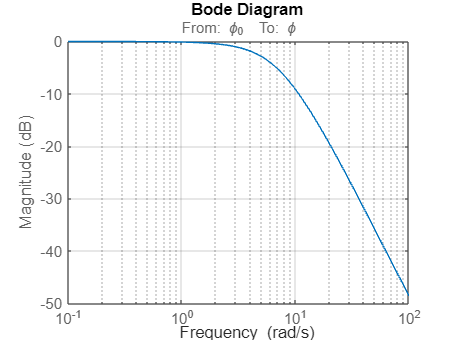

F = getIOTransfer(CL, '\phi_0', '\phi');

figure
bodemag(F)
grid on

We can plot the step response and compare it to the desired one.

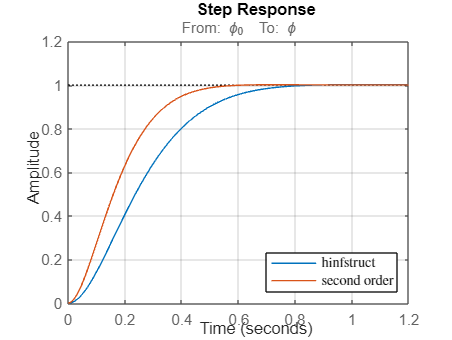

figure
step(F)
hold on
step(F_2)
grid on
legend('hinfstruct','second order', 'location','southeast')


stepinfo(F)

ans = struct with fields:
         RiseTime: 0.4162
    TransientTime: 0.6788
     SettlingTime: 0.6788
      SettlingMin: 0.9031
      SettlingMax: 1.0019
        Overshoot: 0.1938
       Undershoot: 0
             Peak: 1.0019
         PeakTime: 1.0246


The sensitivity and its weight can be plotted to verify nominal performance.

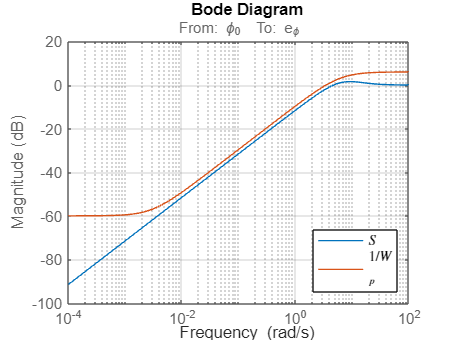

S = getIOTransfer(CL,'\phi_0','e_\phi');
figure
bodemag(S)
grid on
hold on
bodemag(1/W_p)
legend('$S$','$1/W\_p$','interpreter','latex', 'location','southeast')

The same can be done for the control sensitivity.

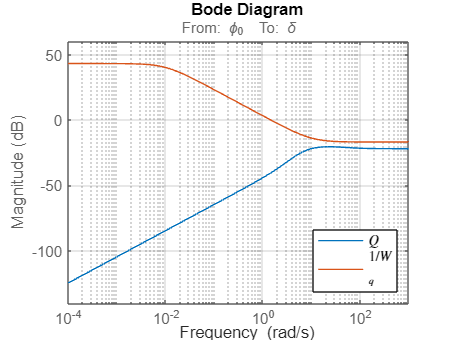

Q = getIOTransfer(CL,'\phi_0','\delta');

figure
bodemag(Q)
grid on
hold on
bodemag(1/W_q)
legend('$Q$','$1/W\_q$','interpreter','latex', 'location','southeast')

The loop transfer function can be shown.

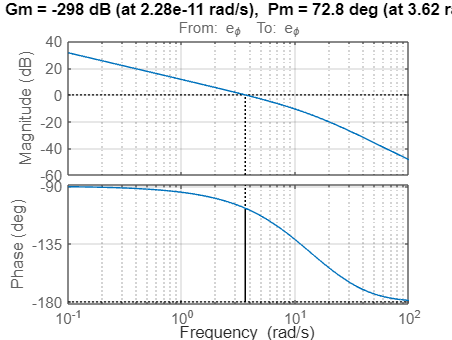

L = (1-S)/S;

figure
margin(L)
grid on

Moreover we can verify control effort limitation.

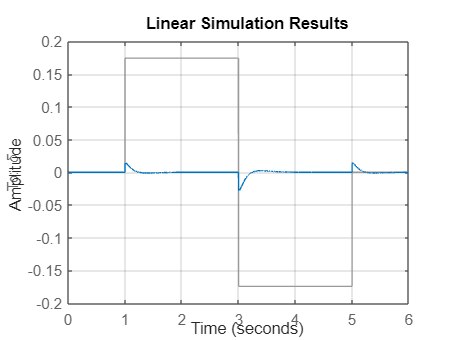

t = linspace(0,6,10^4);
u = 0*(t<=1) + 10*(t>1 & t<= 3) - 10*(t>3 & t<= 5) + 0*(t>5);
u = deg2rad(u);

figure
lsim(Q,u,t);
hold on
grid on

## ***4) Uncertain analysis***

Nominal parameters and uncertainities

Y_v_nom = -0.1068;       % [1/s]         -> 4.26 %
Y_p_nom = 0;            % [m/(s rad)]   -> 2.03%
L_v_nom = 0;       % [rad s/m]     -> 1.83 %
L_p_nom = -2.6478;            % [1/s]         -> 2.01%

Y_d_nom = 0;        % [m/s^2]       ->  % 1.37%
L_d_nom = 450.7085;     % [rad/s^2]     -> 0.81 %


unc_Y_v = 3*4.26;
unc_L_p = 3*2.01;
unc_L_d = 3*0.81;

% Stability Derivatives
Y_v = ureal('Y_v',Y_v_nom,'Perc',unc_Y_v);
Y_p = Y_p_nom;
L_v = L_v_nom;
L_p = ureal('L_p',L_p_nom,'Perc',unc_L_p);

% Control Derivatives
Y_d = Y_d_nom;
L_d = ureal('L_d',L_d_nom,'Perc',unc_L_d);

A_s = [Y_v 0 g; 0 L_p 0; 0 1 0];
B_s = [0 L_d 0]';
C_s = [0, 0, 1];
D_s = 0;


% Uncertain Plant
sys_un = ss(A_s,B_s,C_s,D_s)

Uncertain continuous-time state-space model with 1 outputs, 1 inputs, 3 states.
The model uncertainty consists of the following blocks:
  L_d: Uncertain real, nominal = 451, variability = [-2.43,2.43]%, 1 occurrences
  L_p: Uncertain real, nominal = -2.65, variability = [-6.03,6.03]%, 1 occurrences
  Y_v: Uncertain real, nominal = -0.107, variability = [-12.8,12.8]%, 1 occurrences


sys_un.u = '\delta';
sys_un.y = '\phi';
 
% Nominal Plant
sys_nom = sys_un.NominalValue

sys_nom =
 
  A = 
            x1       x2       x3
   x1  -0.1068        0     9.81
   x2        0   -2.648        0
   x3        0        1        0
 
  B = 
       \delta
   x1       0
   x2   450.7
   x3       0
 
  C = 
         x1  x2  x3
   \phi   0   0   1
 
  D = 
         \delta
   \phi       0
 
Continuous-time state-space model.


sys_nom.u = '\delta';
sys_nom.y = '\phi';


Zeros, poles and step response

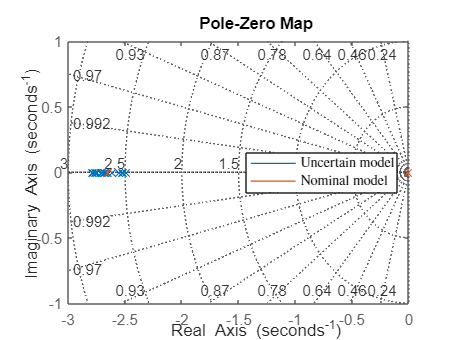

G_delta_phi_nom = tf(sys_nom);

figure
pzplot(sys_un);
hold on 
pzplot(sys_nom);
grid on                               
legend('Uncertain model','Nominal model','location','east')


z_delta_phi = tzero(sys_nom)

z_delta_phi = -0.1068

p_delta_phi = pole(sys_nom)

p_delta_phi =          0
   -2.6478
   -0.1068


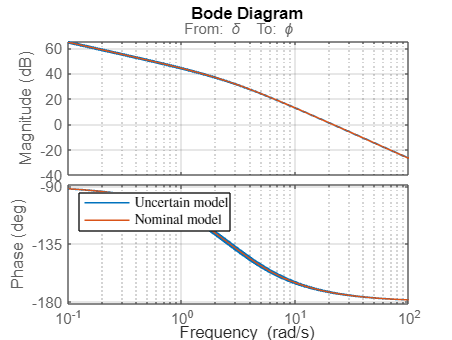


figure 
bode(sys_un)
hold on
bode(sys_nom)
grid on
legend('Uncertain model','Nominal model','location','northwest')

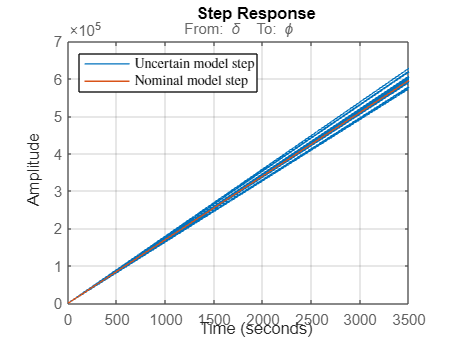


figure 
step(sys_un)
hold on
step(sys_nom)
grid on
legend('Uncertain model step','Nominal model step','location','northwest')

## **5) Robust stability analysis and design**

%Uncertain DI
CAB_inv_s = ss(0, 0, 0, inv(C_s*A_s*B_s));
CAB_inv_s.u = 'e_w' ;
CAB_inv_s.y = '\delta';

C_obs = eye(3,3)

C_obs =      1     0     0
     0     1     0
     0     0     1


sys_state = ss(A_s, B_s ,C_obs , 0);
sys_state.u = '\delta';
sys_state.y = {'v', 'p', '\phi'};

CA_s = ss(zeros(3,3), zeros(3,3), zeros(1,3), C_s*A_s*A_s);
CA_s.u = {'v', 'p', '\phi'};
CA_s.y = 'w_DI';

SumOuter_DI = sumblk('e_w = w - w_DI');

CL_DI = connect(SumOuter_DI, CAB_inv_s, sys_state, CA_s, 'w', '\phi')

Uncertain continuous-time state-space model with 1 outputs, 1 inputs, 2 states.
The model uncertainty consists of the following blocks:
  L_d: Uncertain real, nominal = 451, variability = [-2.43,2.43]%, 2 occurrences
  L_p: Uncertain real, nominal = -2.65, variability = [-6.03,6.03]%, 2 occurrences



SumIn = sumblk('e_\phi = \phi_0 - \phi');
%Block connection
CL_on = connect(CL_DI, R_phi_tuned, '\phi_0', '\phi')

Generalized continuous-time state-space model with 1 outputs, 1 inputs, 4 states, and the following blocks:
  L_d: Uncertain real, nominal = 451, variability = [-2.43,2.43]%, 2 occurrences
  L_p: Uncertain real, nominal = -2.65, variability = [-6.03,6.03]%, 2 occurrences
  R_phi: Tunable 2-DOF PID controller, 1 occurrences.


% Compute M-Delta decomposition of the whole loop
[P , Delta] = lftdata(CL_on);

G_Delta = tf(Delta); %7x7 matrix
G_1 = tf(1)

G_1 =
 
  1
 
Static gain.
Model Properties


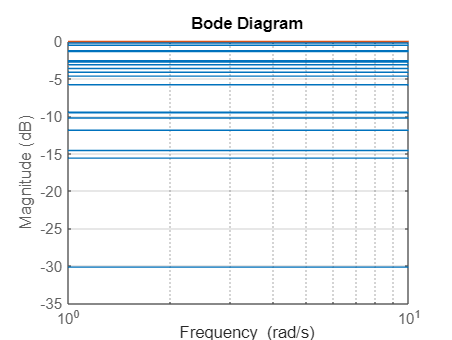


%Verification of AS of Delta |Delta|_dB <= 0 

figure
bodemag(G_Delta(1,1))
hold on
grid on

bodemag(G_1)

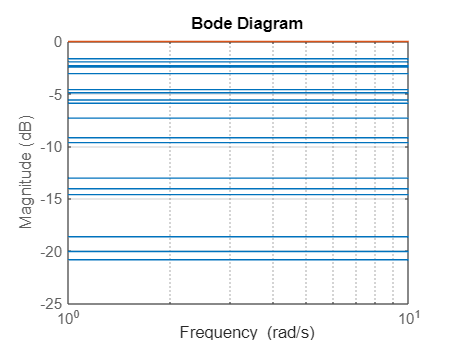


figure
bodemag(G_Delta(2,2))
hold on
grid on

bodemag(G_1)

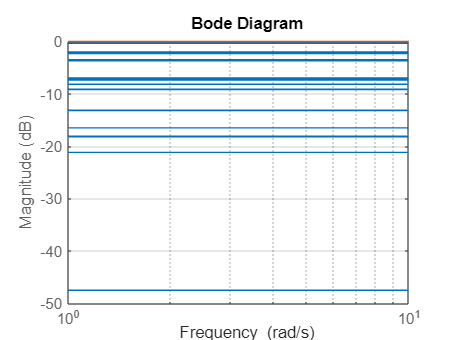



figure
bodemag(G_Delta(3,3))
hold on
grid on

bodemag(G_1)

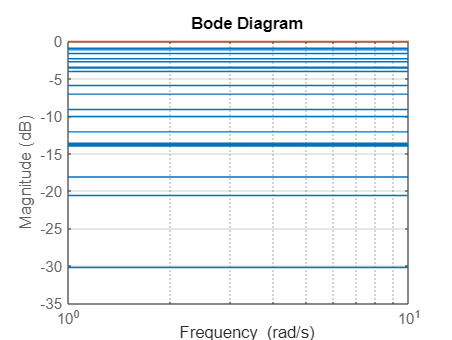



figure
bodemag(G_Delta(4,4))
hold on
grid on

bodemag(G_1)

Delta is AS stable, so condition for SISO RS can be applied to verufy RS: |M|_Db < 0

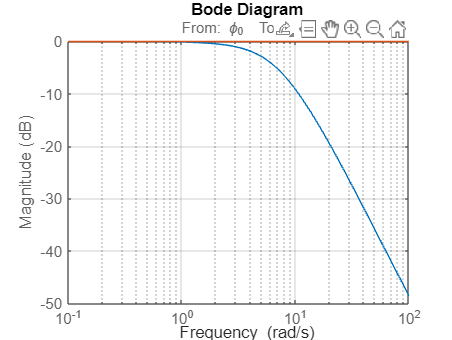

%M verification 
G_P = tf(P);
figure
bodemag(G_P(5,5))
hold on
grid on
bodemag(G_1)

Graphic suggests RS. For an extra check:

[stabmarg,wcu] = robstab(CL_on)

stabmarg = struct with fields:
           LowerBound: 41.0700
           UpperBound: 41.1523
    CriticalFrequency: 1


wcu = struct with fields:
    L_d: 1.3001e-09
    L_p: -9.2117


## 6) Robust performance verification


$$\left|W(j\omega) \bar{F}(j\omega)\right| < 1 \quad \quad \forall \omega$$


is not satisfied we have to proceed redesigning our controller (adding the weight on the complementary sensitivity function).

First we create an array sampling our uncertain model.

sys_un_array = usample(sys_un,500);


Then we can construct our $W(s)$ bounding the relative error using [`ucover`](https://it.mathworks.com/help/robust/ref/lti.ucover.html).

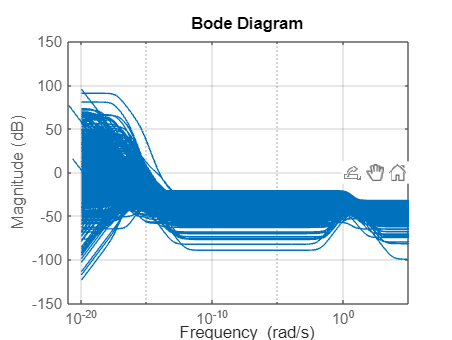

[~,Info] = ucover(sys_un_array,sys_nom,3);

W = Info.W1;

figure
bodemag(W,'r')
hold on
bodemag((sys_nom-sys_un_array)/sys_nom)
grid on

Finally we can verify graphically the robust stability condition.

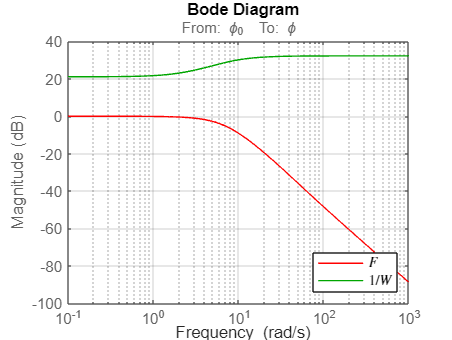

figure
bodemag(F,'r',1/W,'g')
grid on
legend('$F$','$1/W$','interpreter','latex', 'location','southeast')

### 6) Robust performance verification

Robust performance are obtained if and only if 

$\left|W_p(j\omega) \bar{S}(j\omega \right| + \left|W(j\omega) \bar{F}(j\omega \right| \le 1 \quad \quad \forall \omega$.

This condition can be checked graphically.

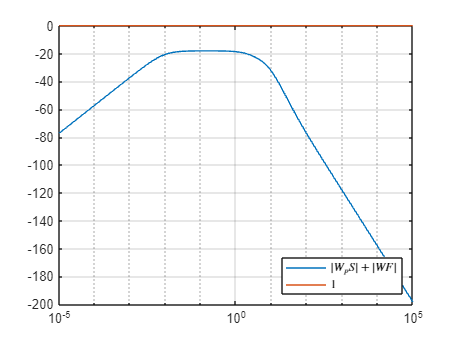

w = logspace(-5,5,500);

FW = bode(F*W,w); 
SW = bode(S*W_p,w);

figure
semilogx(w, 20*log10(squeeze(FW)) + 20*log10(squeeze(SW)))
hold on 
semilogx(w,20*log10(w./w))
grid on
legend('$|W_p S|+|W F|$','$1$','interpreter','latex', 'location','southeast')